clear all
% DATA FROM FALL TEST DRIVE FOR REAR WHEEL SPEED
fs = 333; %Hz
pre_data = readtable('drive-data/11-25-24/Decoded/6_cleanedData.csv');

pre_data.target = pre_data.RearRightWheelSpeed;

%sample rates of different signals:
avg_sample_rate.RR = mean(diff(pre_data.Time(~isnan(pre_data.RearRightWheelSpeed))));
avg_sample_rate.RL = mean(diff(pre_data.Time(~isnan(pre_data.RearLeftWheelSpeed))));
avg_sample_rate.FL = mean(diff(pre_data.Time(~isnan(pre_data.FrontLeftWheelSpeed))));
avg_sample_rate.FR = mean(diff(pre_data.Time(~isnan(pre_data.FrontRightWheelSpeed))));
avg_sample_rate.GPS = mean(diff(pre_data.Time(~isnan(pre_data.GPSSpeed))));
avg_sample_rate %printout (in seconds)

avg_sample_rate = struct with fields:
     RR: 0.0030
     RL: 0.0039
     FL: 0.0185
     FR: 0.0185
    GPS: 0.0500


post_data = readtable('cleanedDataRWSLeft_03052025');

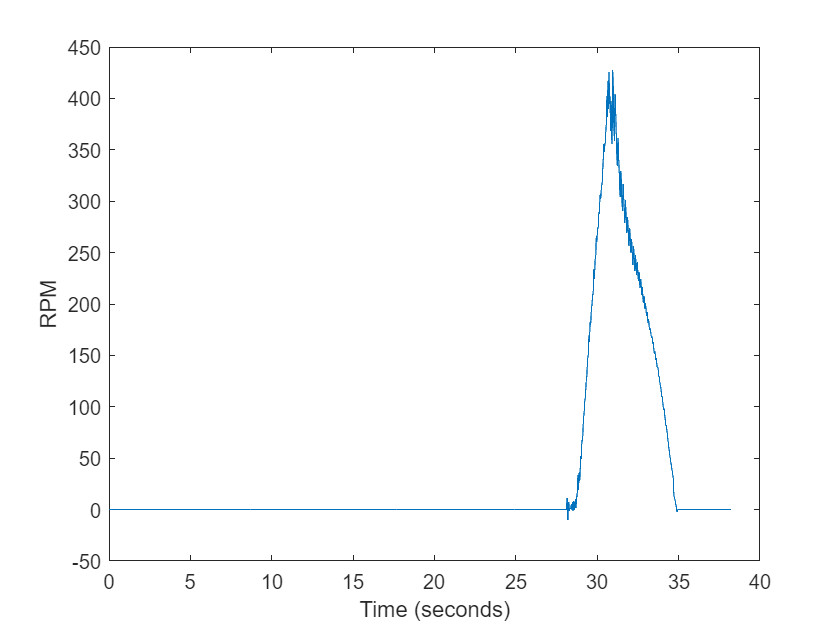

t_post = post_data.Time_s_(~isnan(post_data.MotorSpeed_rpm_));
x_post = post_data.MotorSpeed_rpm_(~isnan(post_data.MotorSpeed_rpm_));

t = pre_data.Time(~isnan(pre_data.target));
x = pre_data.target(~isnan(pre_data.target));

% For post_data arrays:
valid_post = x_post < 50;       % Find indices where x_post is below 100
t_post_trim = t_post(valid_post); % Keep corresponding time values
x_post_trim = x_post(valid_post); % Keep the speed values

% For pre_data arrays:
valid_pre = x < 100;       % Find indices where x is below 100
t_trim = t(valid_pre);     % Keep corresponding time values
x_trim = x(valid_pre);     % Keep the speed values

figure;
plot(t, x)
xlabel('Time (seconds)')
ylabel('RPM')

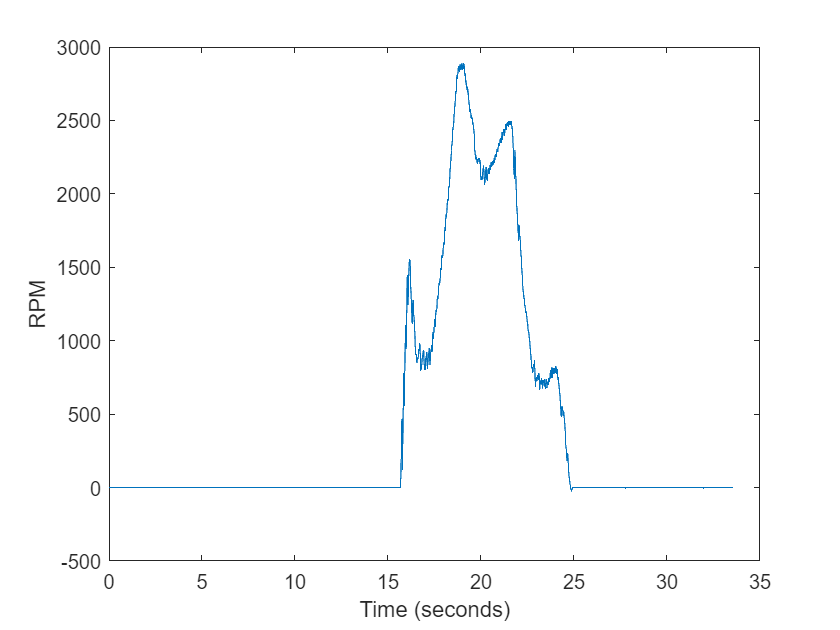

figure;
plot(t_post, x_post)
xlabel('Time (seconds)')
ylabel('RPM')

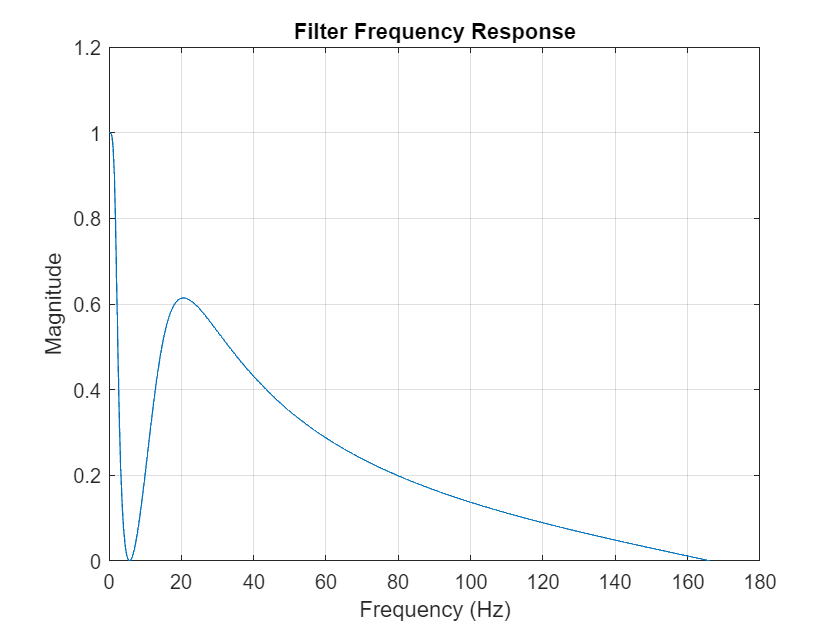

% 3-16 bandstop O2, 20 low pass O1
b_combined_filter = [0.13300213 -0.39596107  0.26297637  0.26297637 -0.39596107  0.13300213 0.];
a_combined_filter = [1.         -4.28828427  7.36155126 -6.32454063  2.71888733 -0.46757883 0. ];


y = filter(b_combined_filter, a_combined_filter, x);
y_post = filter(b_combined_filter, a_combined_filter, x_post);
%y = filter(b, a, x);

b_freqz = b_combined_filter;
a_freqz = a_combined_filter;

[h, w] = freqz(b_freqz, a_freqz, 1024, fs);
figure;
plot(w, abs(h));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Filter Frequency Response');
grid on;

# **Pre Data**

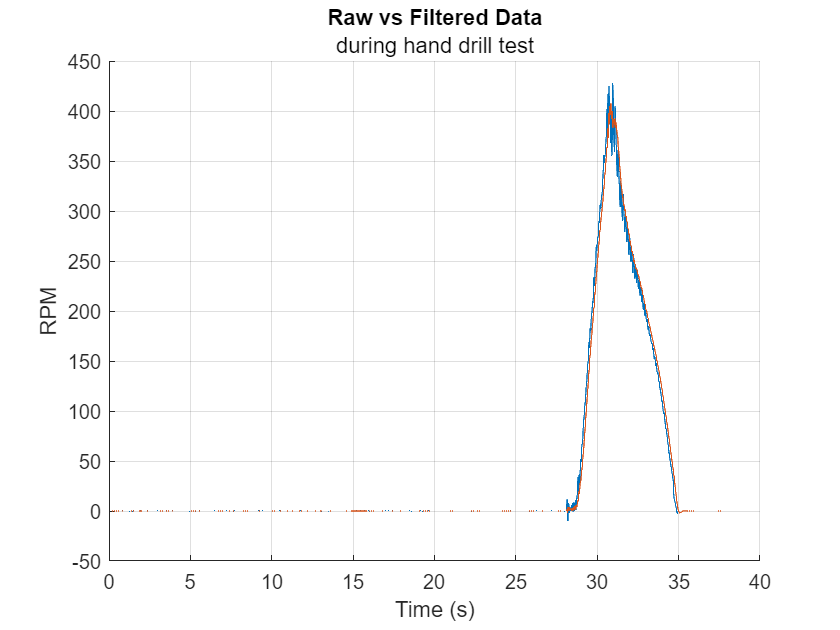

Ts = mean(diff(pre_data.Time(~isnan(pre_data.target))));

clf
hold on
%t = pre_data.Time(~isnan(pre_data.target));
%x = pre_data.target(~isnan(pre_data.target));
plot(t, x)
plot(t, y)

hold off
title("Raw vs Filtered Data")
subtitle("during hand drill test")
xlabel('Time (s)');
ylabel('RPM');
grid on


% perform xcorr of this data
[r, lags] = xcorr(x, y, 500, 'normalized');

% max correlation:
[max_r, idx_max_r] = max(r);

time_index_lag = abs(lags(idx_max_r));

% time displacement of max correlation (i.e. lag of GPS speed):
max_correlation_lag = -1 * mean(diff(t)) * lags(idx_max_r)

max_correlation_lag = 0.1140

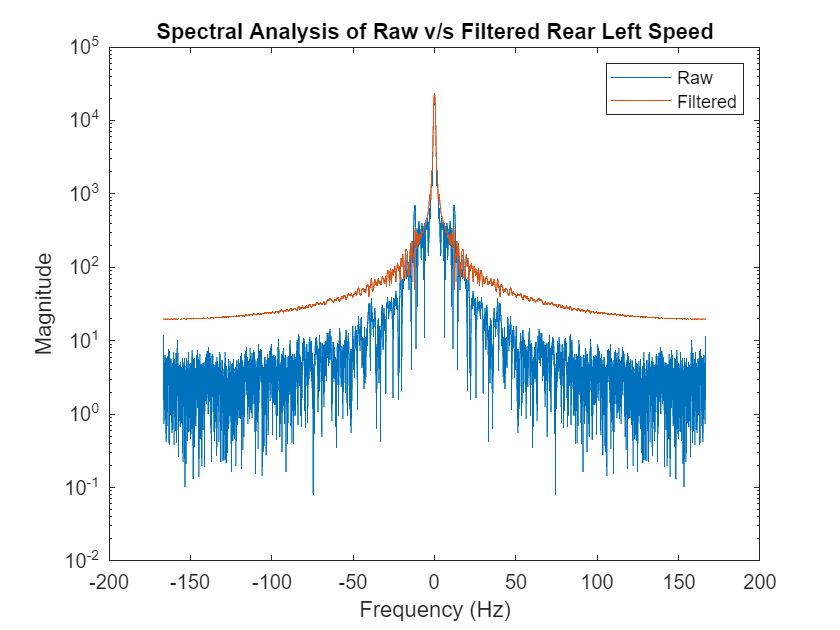

x_placeholder = x_trim;
z = fft(x_placeholder);
fs = 1/Ts;
f = (0:length(z)-1)*fs/length(z);
%plot(f,abs(y))

figure;
n = length(x_placeholder);
fshift = (-n/2:n/2-1)*(fs/n);
zshift = fftshift(z);
semilogy(fshift,abs(zshift))
hold on
xlabel('Frequency (Hz)')
ylabel('Magnitude')


title('Spectral Analysis of Raw v/s Filtered Rear Left Speed')
x_placeholder = y(valid_pre);
z = fft(x_placeholder);
fs = 1/Ts;
f = (0:length(z)-1)*fs/length(z);
%plot(f,abs(y))

n = length(x_placeholder);
fshift = (-n/2:n/2-1)*(fs/n);
zshift = fftshift(z);
semilogy(fshift,abs(zshift))
legend('Raw', 'Filtered')
hold off

# **Post Data**

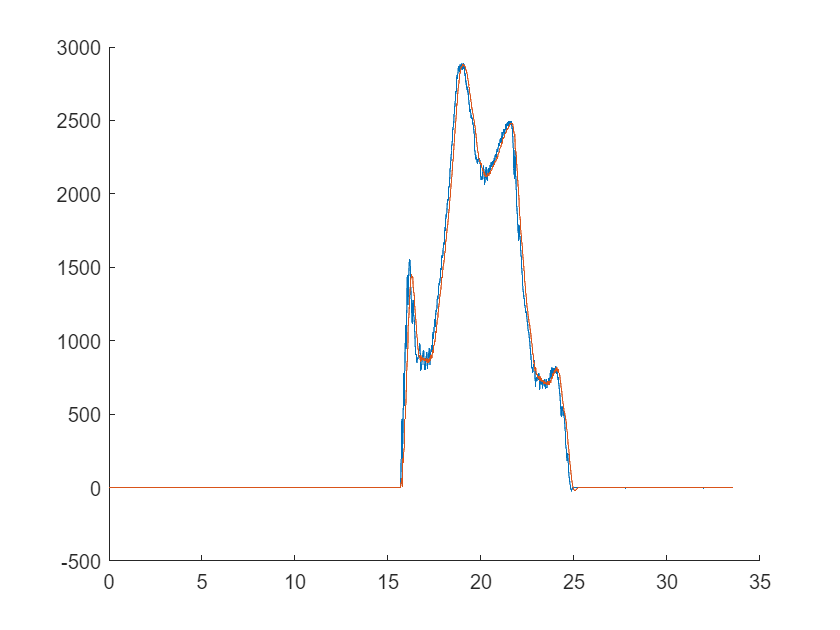

Ts = mean(diff(post_data.Time_s_(~isnan(post_data.MotorSpeed_rpm_))));

clf
hold on
%t = pre_data.Time(~isnan(pre_data.target));
%x = pre_data.target(~isnan(pre_data.target));
plot(t_post, x_post)
plot(t_post, y_post)

% perform xcorr of this data
[r, lags] = xcorr(x, y, 500, 'normalized');

% max correlation:
[max_r, idx_max_r] = max(r);

time_index_lag = abs(lags(idx_max_r));

% time displacement of max correlation (i.e. lag of GPS speed):
max_correlation_lag = -1 * mean(diff(t)) * lags(idx_max_r)

max_correlation_lag = 0.1140

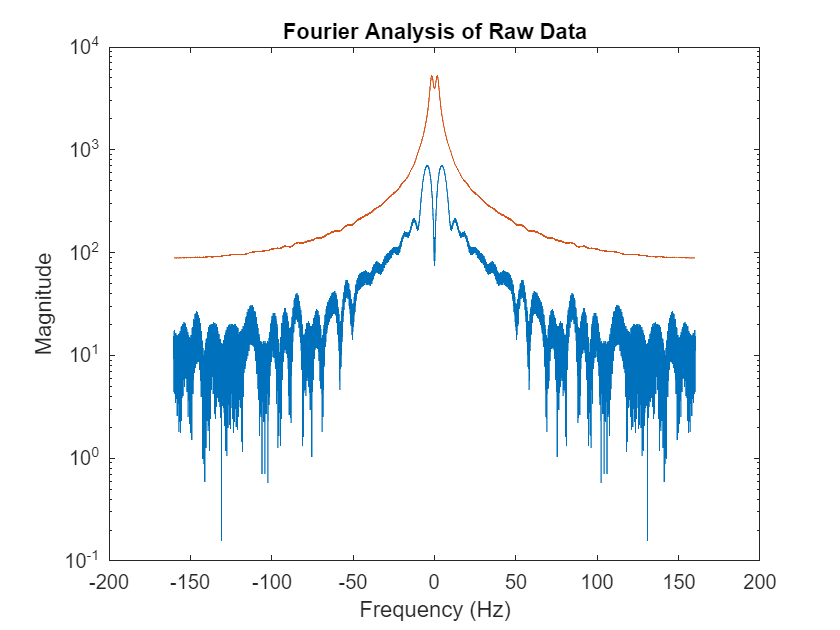

x_placeholder = x_post_trim;
z = fft(x_placeholder);
fs = 1/Ts;
f = (0:length(z)-1)*fs/length(z);
%plot(f,abs(y))

figure;
n = length(x_placeholder);
fshift = (-n/2:n/2-1)*(fs/n);
zshift = fftshift(z);
semilogy(fshift,abs(zshift))
hold on
xlabel('Frequency (Hz)')
ylabel('Magnitude')


title('Fourier Analysis of Raw Data')
x_placeholder = y_post(valid_post);
z = fft(x_placeholder);
fs = 1/Ts;
f = (0:length(z)-1)*fs/length(z);
%plot(f,abs(y))

n = length(x_placeholder);
fshift = (-n/2:n/2-1)*(fs/n);
zshift = fftshift(z);
semilogy(fshift,abs(zshift))
hold off